% Set up
clc;
close all;
clear;

## load data

edfFilename = 'R1_edf.mat';
xmlFilename = 'R1_xml.mat';
load(edfFilename);
load(xmlFilename);

## select needed data(eeg)

hdr.label

ans = 1×14 cell 数组
    {'SaO2'}    {'HR'}    {'EEGsec'}    {'ECG'}    {'EMG'}    {'EOGL'}    {'EOGR'}    {'EEG'}    {'THORRES'}    {'ABDORES'}    {'POSITION'}    {'LIGHT'}    {'NEWAIR'}    {'OXstat'}


% We can know from the hdr that the 3rd and the 8th 
% channel of the record is EEG signal
Fs = hdr.samples(3);

% every epoch lasts 30 seconds
epochNumber = 10; % start epoch No.
epochAmount = 1; % How much epoches to cut
epochStart = ((epochNumber-1)*Fs*30)+1;
epochEnd = epochStart + epochAmount*30*Fs;

t = linspace(0,epochAmount*30,epochAmount*30*Fs+1);
eeg1 = record(8,epochStart:epochEnd); 
eeg2 = record(3,epochStart:epochEnd);

numberOfEpochs = length(record(3,:)')/(30*Fs);

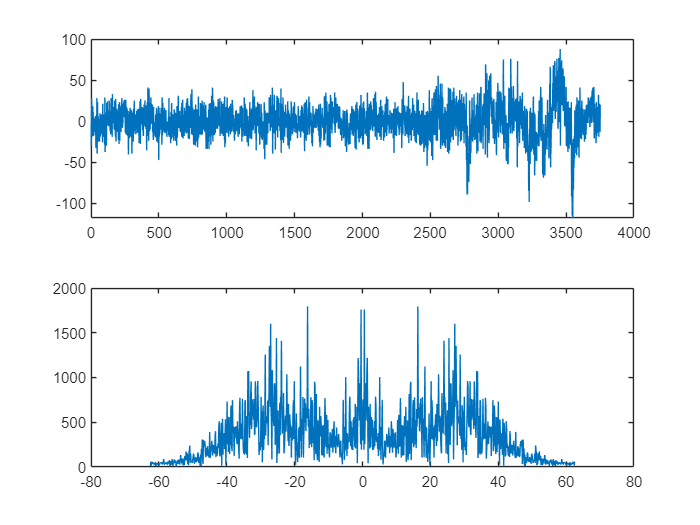

%% first plot
figure(1)
subplot(2,1,1)
plot(eeg1)
subplot(2,1,2)
plot(eeg2)

% FFT
N = 1024;
EEG1 = abs(fftshift(fft(eeg1,N)));
fshift=linspace(-0.5*Fs,0.5*Fs,N);     % fftshift x axis
plot(fshift,EEG1)

## remove the baseline drift

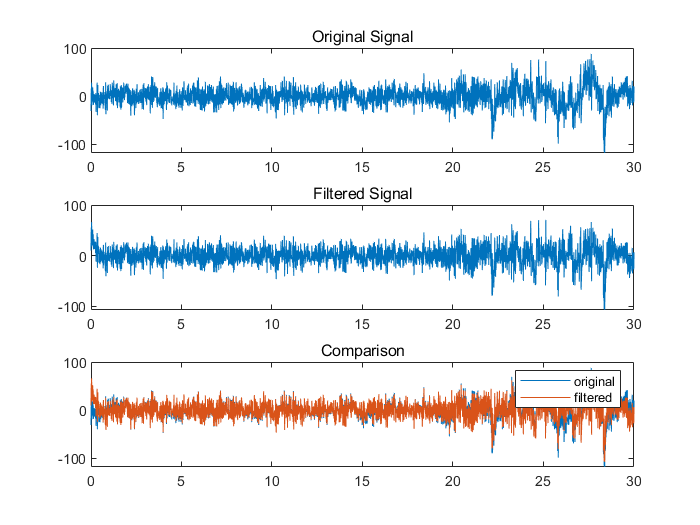

eeg1_filtered =     9.8861   43.5816   54.7282   46.2672   66.2381   57.7783   17.9466   19.2923   41.2273   31.7909   25.2970   49.1968   51.5295   23.4718   20.9062   42.8525   27.5460   12.2418   30.2733   26.7388   30.0697   32.4231   23.0147   15.5701   13.0306   21.2788   27.5696   22.0993   23.4953   25.8755   16.4948    5.1574   11.4710   27.5928   17.2482  -12.6998   -8.3297   19.5744   21.0126   11.6711    7.2364   15.5518   44.4603   30.2366  -24.1781  -11.9209   36.6160   37.1190   18.9999   11.6706


eeg1_filtered = baseline_drift_removal(eeg1,Fs)

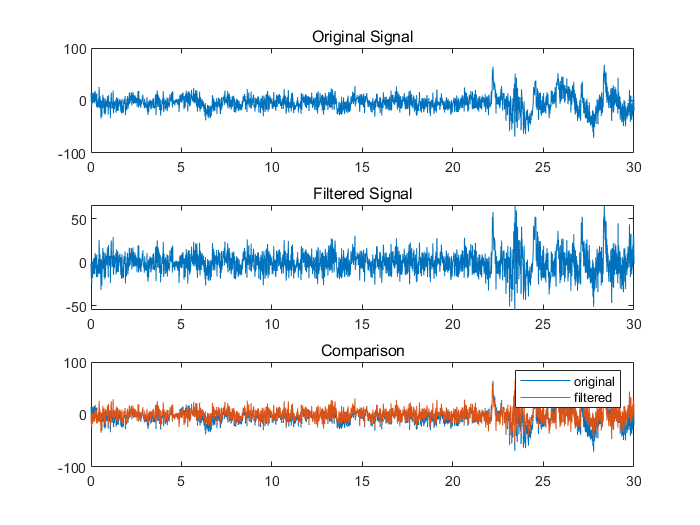

eeg2_filtered =    -1.4281   -7.0242  -17.5214  -19.1942  -18.9054  -24.4983  -10.4827    1.5726   -0.0970    1.1750   -6.3762  -17.8486  -14.6149  -12.3615   -9.1275   -7.8543   -8.5418   -2.3668    4.7885   -4.7230  -13.2545   -2.1785    4.9755    0.3644   -3.2669  -12.7812  -13.4726   -0.4392   10.6325    9.9387   -2.5207   -5.1772   -6.8543   -2.6502    6.4547    3.7936   -1.8099   -9.3755  -16.9425   -7.8443    9.0955   -1.4172   -6.0492   -2.8397   -7.4751  -11.1319  -16.7513   -8.6471   -4.4663   -6.1699



eeg2_filtered = baseline_drift_removal(eeg2,Fs)

## Muscle noise filtering

## Power line interference removal

## Any other artefact detection and handling